[ws,x] = wpfun('db3', 3, 10);

s00 = upsample(ws(1,:), 2); 
w00 = upsample(ws(2,:), 2); 

[w10, x1] = DT(ws(3,:), x, 1, 0);
[w11, x1] = DT(ws(3,:), x, 1, 1);
[w12, x1] = DT(ws(3,:), x, 1, 2);
[w13, x1] = DT(ws(3,:), x, 1, 3);
[w14, x1] = DT(ws(3,:), x, 1, 4);
[w15, x1] = DT(ws(3,:), x, 1, 5);

H = zeros([8 8]);

basis = [s00 ; w00 ; w10 ; w11 ; w12 ; w13 ; w14 ; w15];
basisdd = [doublediff(basis(1:2,:),x); doublediff(basis(3:end,:), x1)];
a = w11; b = w11; xa = x1; xb = x1; 
trapz(a.* b ) * xb(2)

ans = 0.9998


H = zeros([8 8]);

for i = 3:8
    for j = i:8
        H(i, j) = trapz(basis(i,:).*basisdd(j,:))*x1(2);
    end
end
for i = 1:2
    for j = i:2
        H(i, j) = trapz(basis(i,:).*basisdd(j,:))*x(2);
    end
end
for i = 1:2
    for j = i:8
        H(i, j) = trapz(basis(i,:).* upsample(downsample(basisdd(j,:),2),2) )*x(2);
    end
end

H = H + H' - diag(diag(H))

H =    -1.3143   -0.6990    7.4401   -4.6586   -6.2555    5.4428    0.7969   -1.7382
   -0.6990   -9.1707    1.9635    1.3472  -18.7607   39.3031  -39.7882   22.1586
    7.4401    1.9635 -773.2492  -66.4203   12.9112   -1.7314   -0.0211         0
   -4.6586    1.3472  -66.4203 -773.2491  -66.4203   12.8591   -1.7314   -0.0211
   -6.2555  -18.7607   12.9112  -66.4203 -773.2491  -66.1790   12.8591   -1.7314
    5.4428   39.3031   -1.7314   12.8591  -66.1790 -773.2491  -66.4203   12.9112
    0.7969  -39.7882   -0.0211   -1.7314   12.8591  -66.4203 -773.2491  -66.4203
   -1.7382   22.1586         0   -0.0211   -1.7314   12.9112  -66.4203 -773.2491


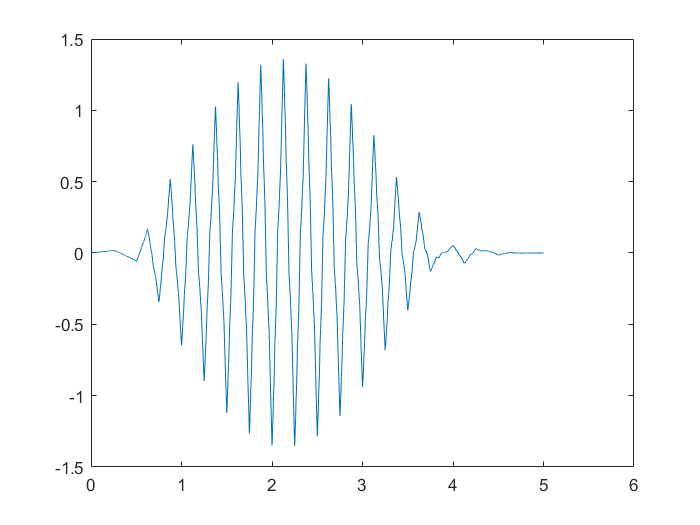


[v, d] = eig(H);

f =(v(:,1)' * basis);
plot(x1,f)


% CHK = zeros([8 8]);
% 
% basis = [s00 ; w00 ; w10 ; w11 ; w12 ; w13 ; w14 ; w15];
% a = w11; b = w11; xa = x1; xb = x1; 
% trapz(a.* b ) * xb(2)
% 
% CHK = zeros([8 8]);
% 
% for i = 3:8
%     for j = i:8
%         CHK(i, j) = trapz(basis(i,:).*basis(j,:))*x1(2);
%     end
% end
% 
% for i = 1:2
%     for j = i:2
%         CHK(i,j) = trapz(basis(i,:).*basis(j,:))*x(2); % the zeros in between, not a problem
%     end
% end
% 
% for i = 1:2
%     for j = 3:8
%         CHK(i,j) = trapz(basis(i,:) .* upsample(downsample(basis(j,:),2),2)) * x(2);
%     end
% end
% 
% CHK = CHK + CHK' - diag(diag(CHK));
% CHK



function [DTw, DTx] = DT(w,x,k,n)   
    %keep n <= (2K - 1)(2^k - 1)
    DTw = w;
    DTx = x+n;
    
    DTw = 2^(k/2)*DTw;
    DTx = DTx/(2^k);
    
    newxstep = DTx(2) - DTx(1);
    Lpad = round(DTx(1) / newxstep);
    
    DTx = wextend('1', 'asymw', DTx, length(DTx)*(2^k - 1), 'r');
    
    DTw = [DTw , zeros(1,(length(DTx) - length(DTw)))];
    DTw = circshift(DTw, Lpad); DTw(1:Lpad) = zeros(1, Lpad);   
    DTx = wextend('1', 'asymw', DTx, Lpad, 'l');
    
    DTx = DTx(1:length(DTw));
    
end

function [wd, xd] = singlediff(w, x)
    wd = gradient(w)/(x(2) - x(1));
    xd = x;
end

function [wdd, xdd] = doublediff(w, x)
    wd = gradient(w)/(x(2) - x(1));
    wdd = gradient(wd)/(x(2) - x(1));
    xdd = x;
end

